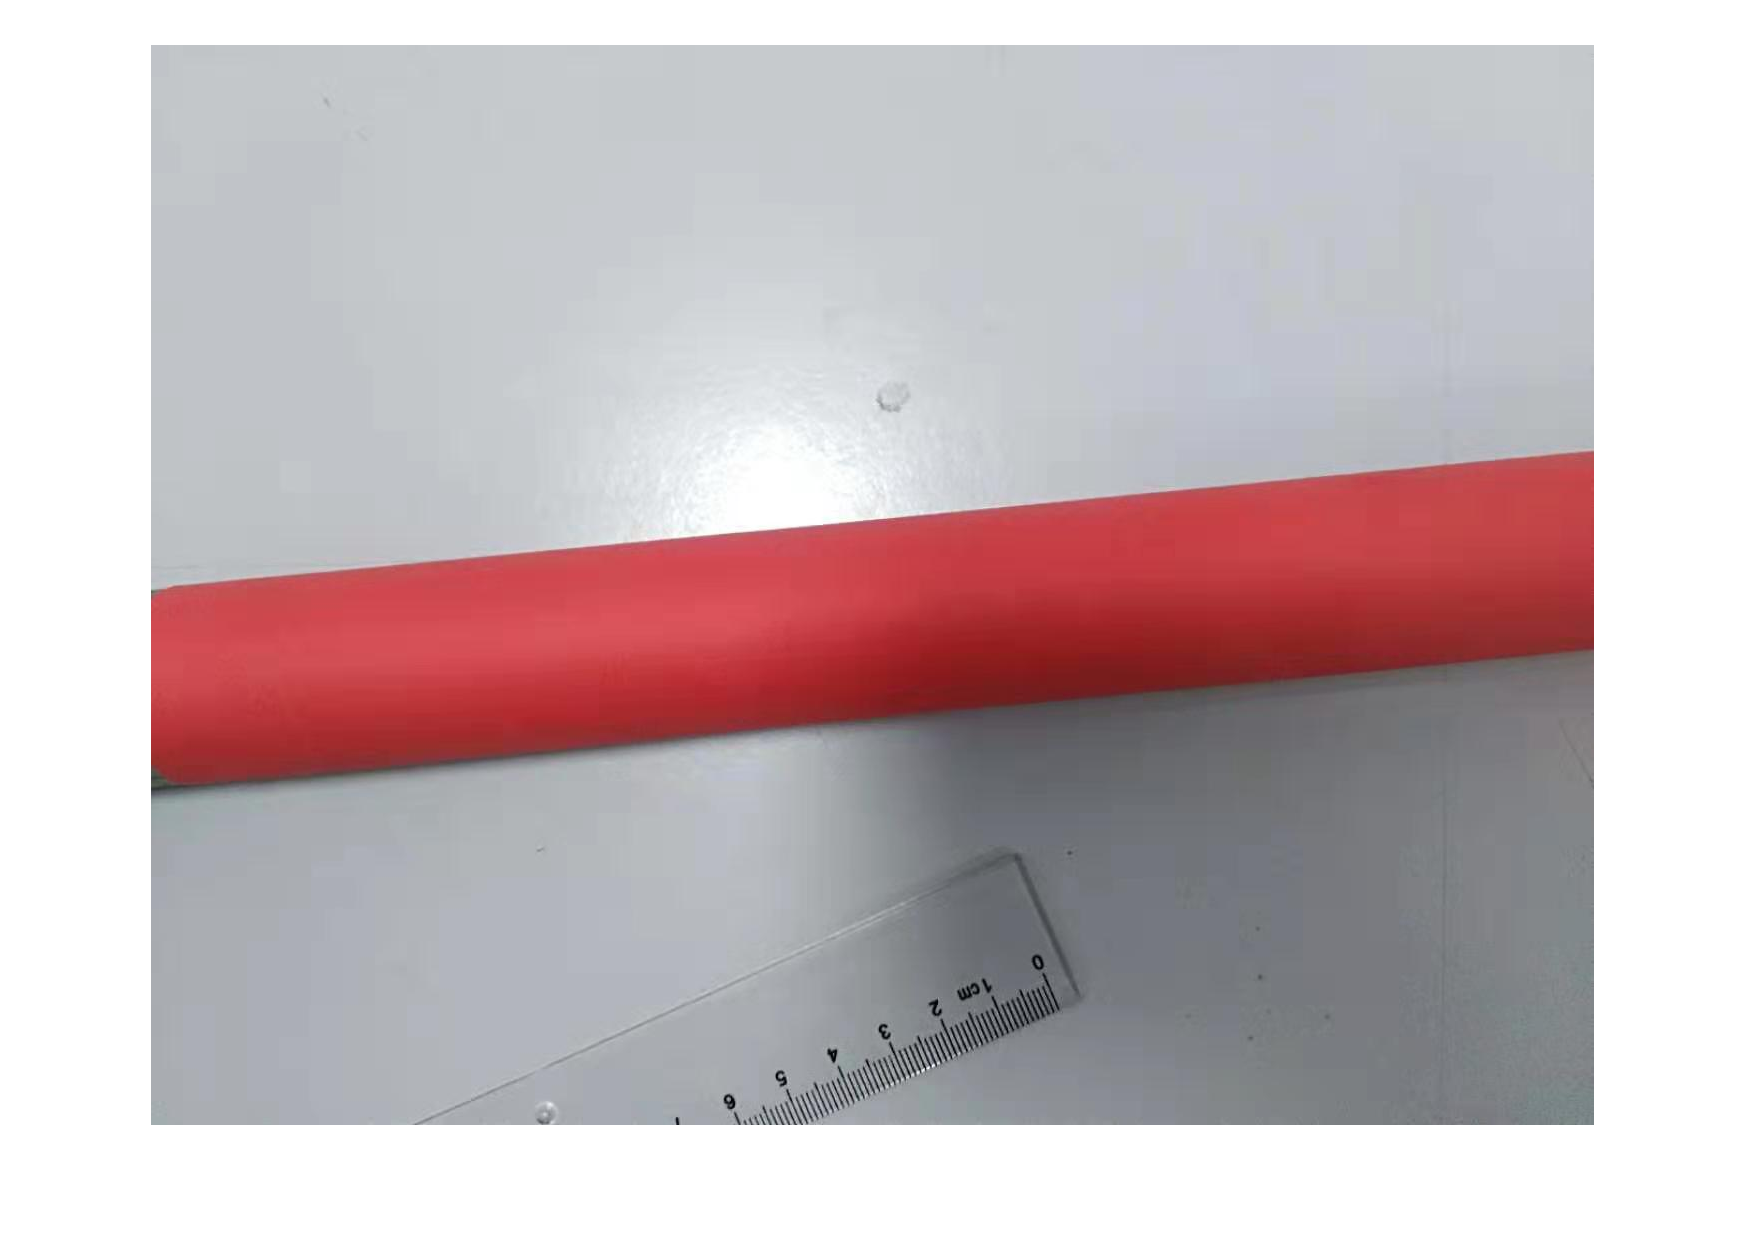

img = imread("./data/3.jpg");
img = im2double(img);

figure, imshow(img);

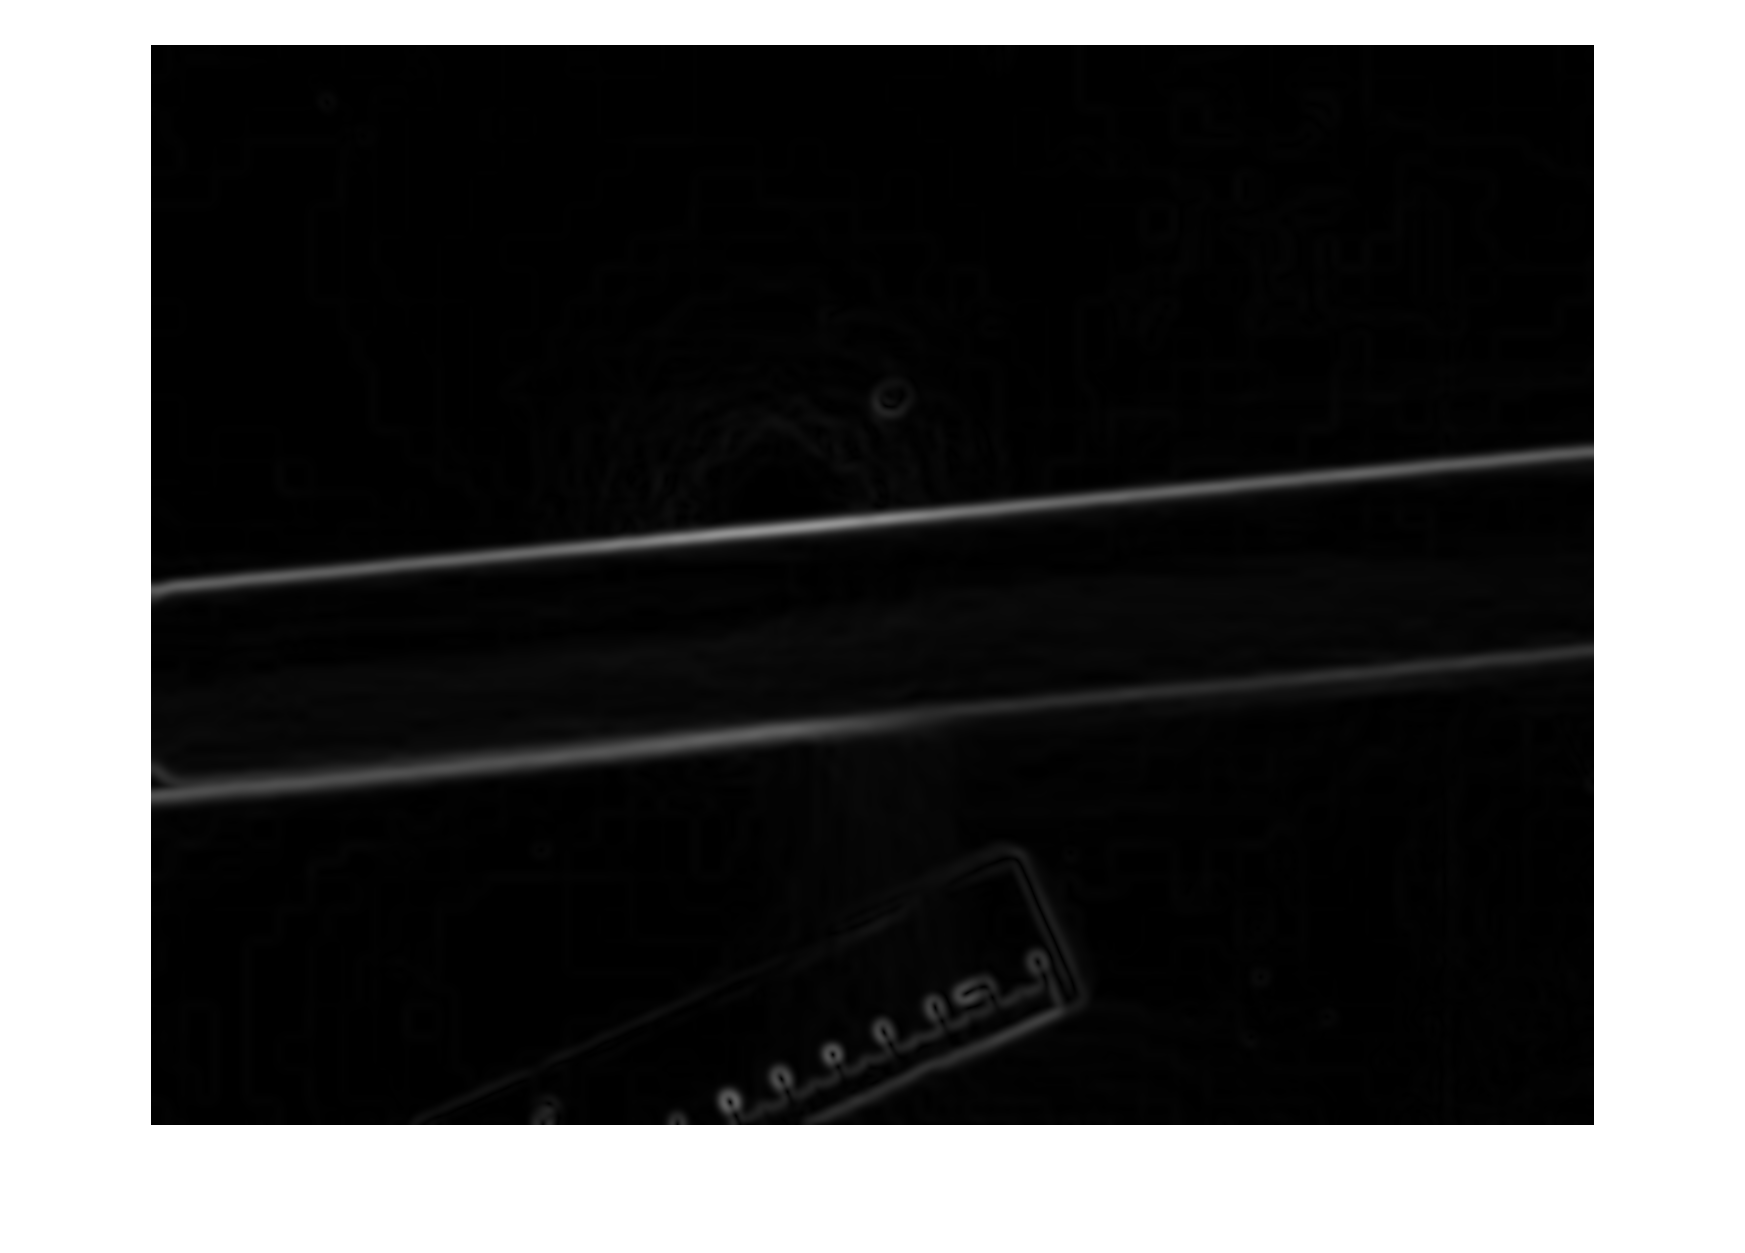

edges = compute_edges(img,5);

figure, imshow(edges);

width=size(edges,2);
height=size(edges,1);

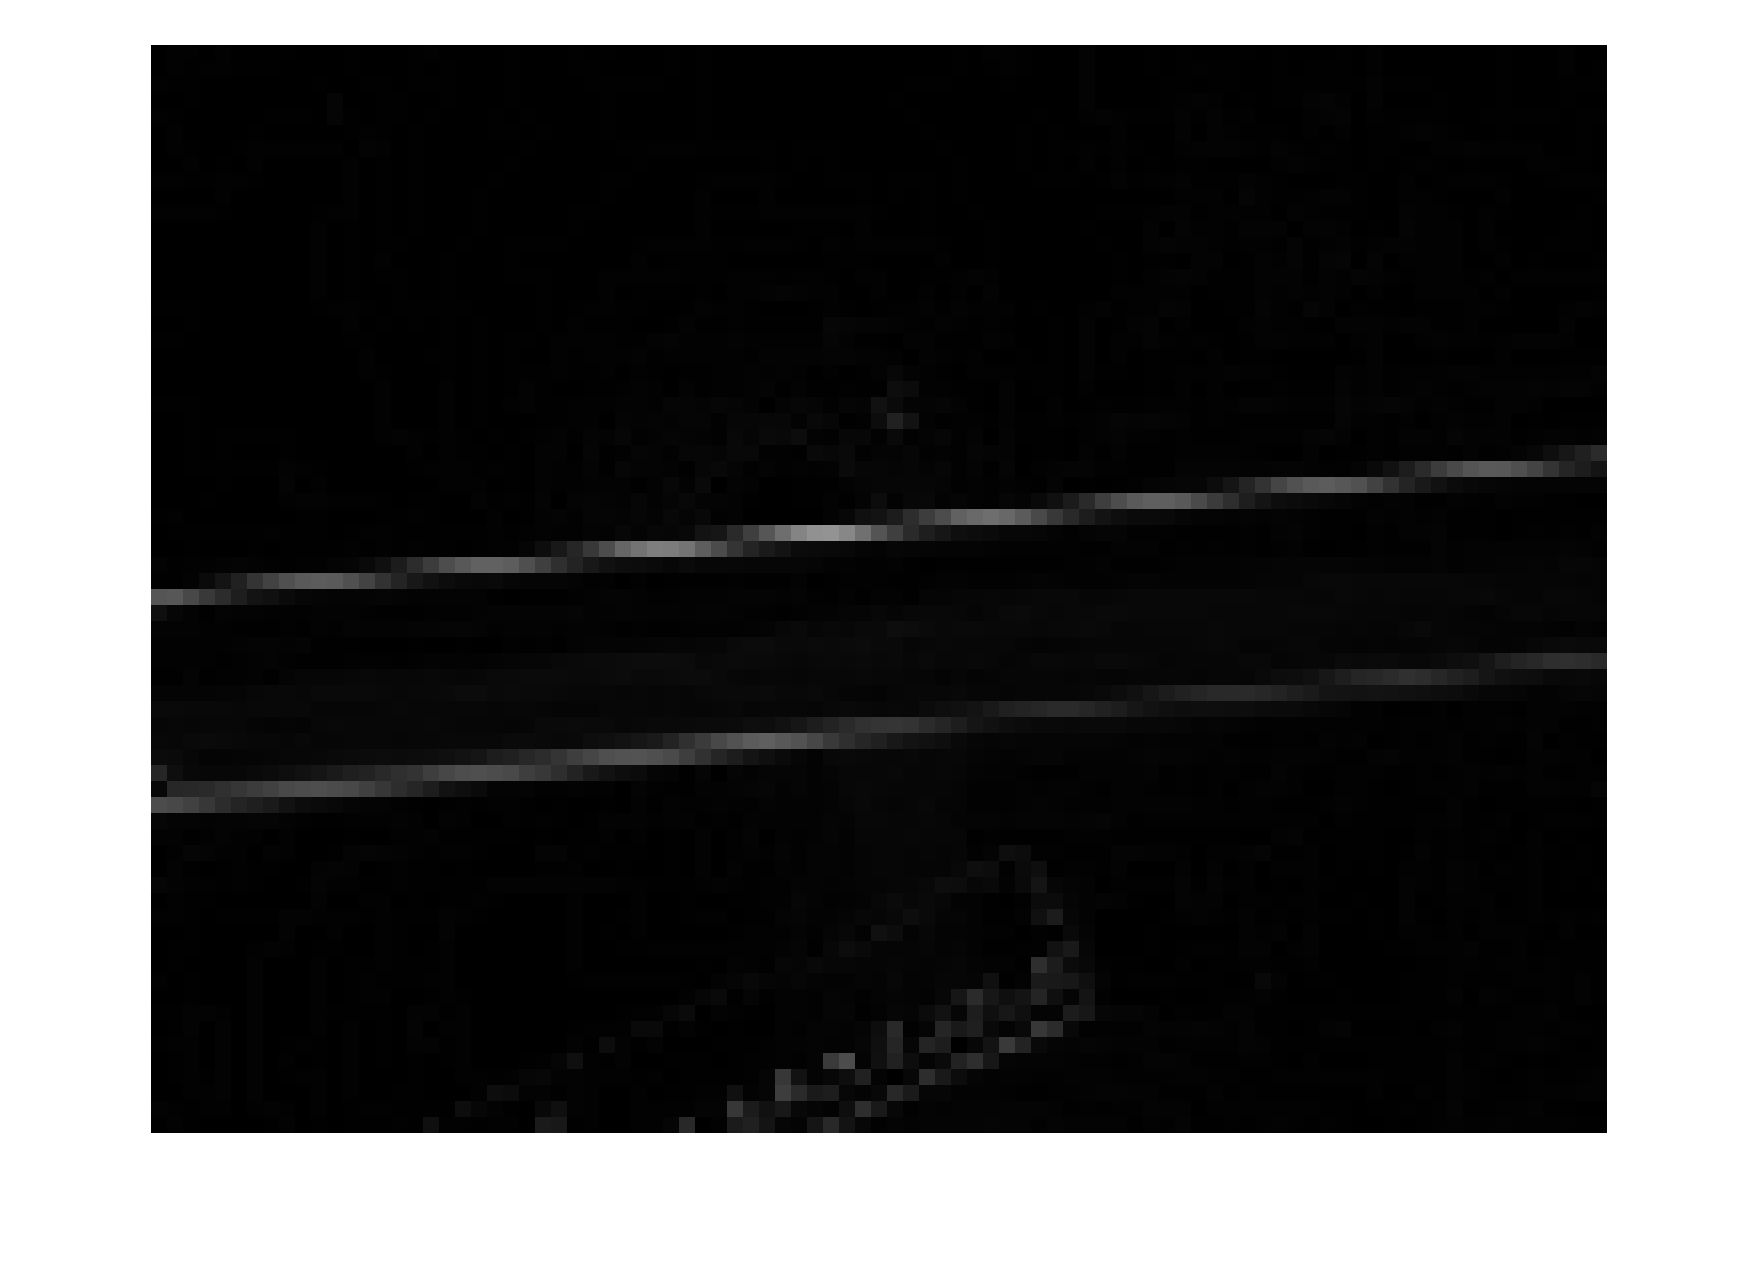

shrink_scale = 16;
edges_shrinked = edges(1:shrink_scale:end,1:shrink_scale:end);

figure; imshow(edges_shrinked,"InitialMagnification",shrink_scale*100), hold on

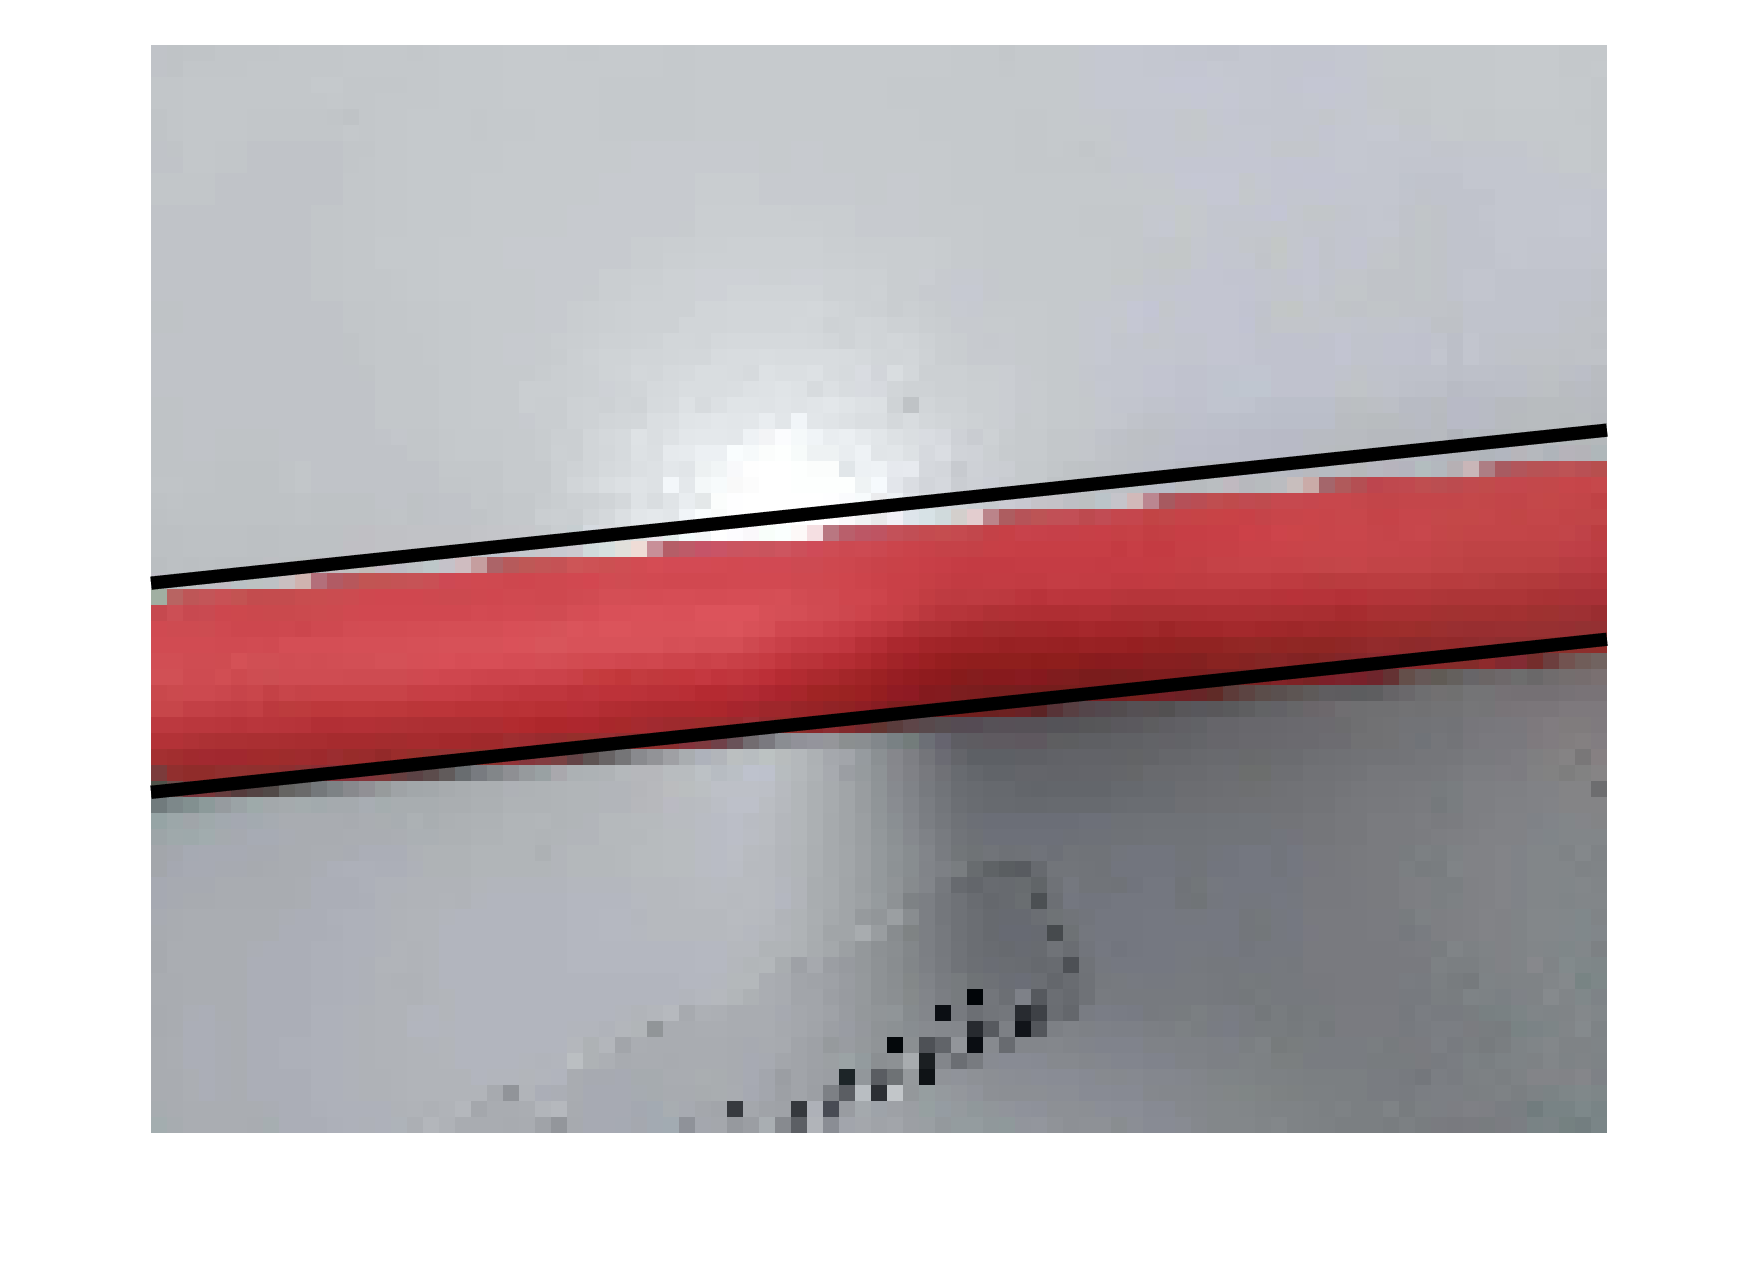

[theta1, rho1_shrinked, theta2, rho2_shrinked] = find_parallel(edges_shrinked,0.03);

img_shrinked = img(1:shrink_scale:end,1:shrink_scale:end,:);
figure; imshow(img_shrinked,"InitialMagnification",shrink_scale*100), hold on
plot_line(width,height,theta1,rho1_shrinked);
plot_line(width,height,theta2,rho2_shrinked);

rho1 = rho1_shrinked * shrink_scale;
rho2 = rho2_shrinked * shrink_scale;

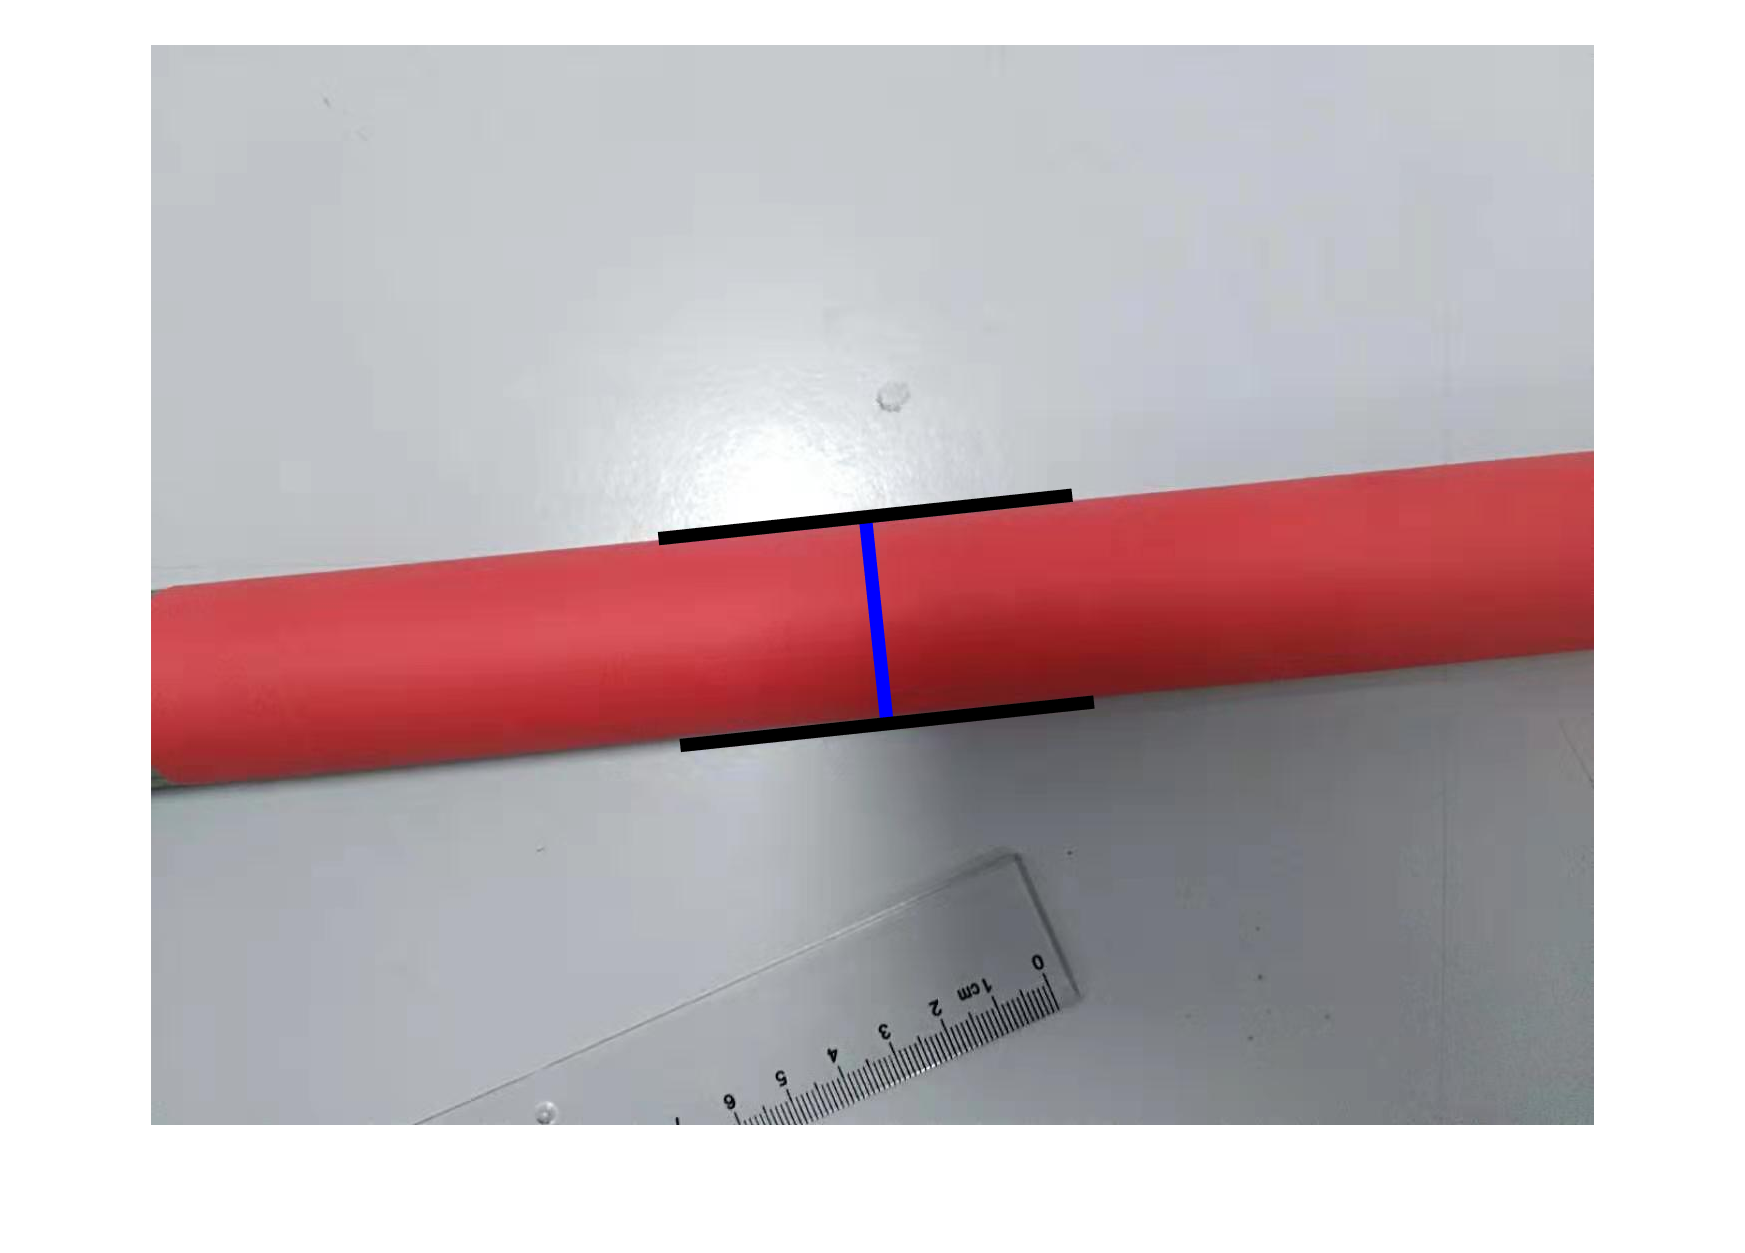

theta = (theta1 + theta2) / 2;
rho = (rho1 + rho2) / 2;

sin_theta = sin(theta);
cos_theta = cos(theta);

xc = width / 2;
yc = height / 2;

xpc = xc * sin_theta * sin_theta + cos_theta * (rho - yc * sin_theta);
ypc = yc * cos_theta * cos_theta + sin_theta * (rho - xc * cos_theta);

pc = [xpc, ypc];
n = [cos_theta, sin_theta];
d = (rho1 - rho2) / 2;
p1 = pc + n * d;
p2 = pc - n * d;

figure, imshow(img), hold on
plot_ruler(p1,p2);